% load the fixed (reference) image and moving image
% image can be resized if size has big differences 
fixedImage=imread('HE_resize.png')

fixedImage = 1363×1187×3 uint8 array
fixedImage(:,:,1) =

   196   218   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210   210

movingImage=imread('RNA_map.png')

movingImage = 1363×1187×3 uint8 array
movingImage(:,:,1) =

   247   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

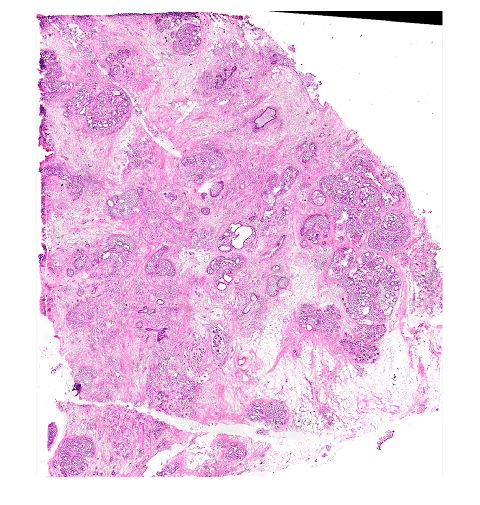


imshow(fixedImage)

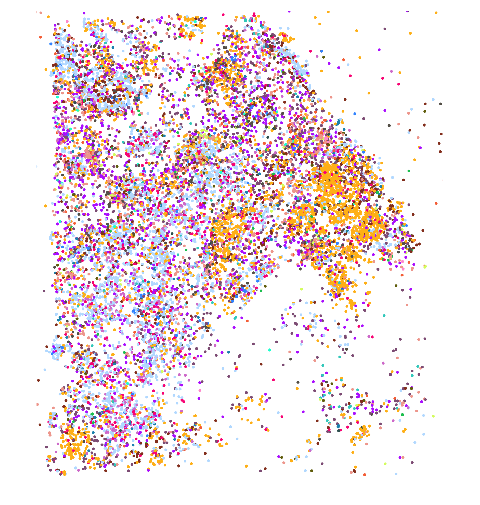

imshow(movingImage)

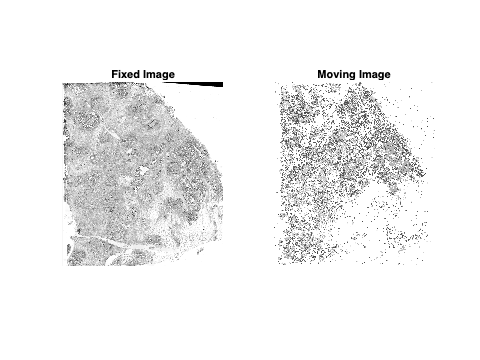


% Display the images
figure;
subplot(1, 2, 1); imshow(fixedImage); title('Fixed Image');
subplot(1, 2, 2); imshow(movingImage); title('Moving Image')

% Convert to grayscale if the images are RGB
fixedGray = rgb2gray(fixedImage);
movingGray = rgb2gray(movingImage);

% Resize the moving image to match the fixed image (if required)
movingGray = imresize(movingGray, size(fixedGray));


subplot(1, 2, 1); imshow(fixedGray); title('Fixed Image');
subplot(1, 2, 2); imshow(movingGray); title('Moving Image')

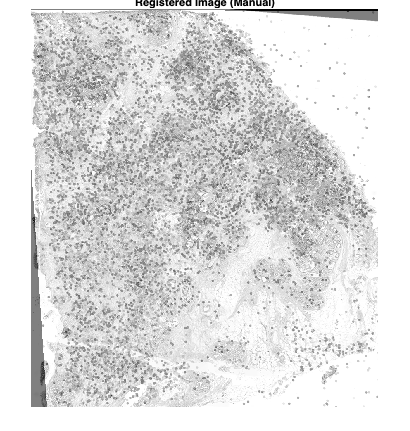


% Open control point selection tool
[movingPoints, fixedPoints] = cpselect(movingGray, fixedGray, 'Wait', true);

% control point selection tool window will pop up, at least 3 or 4 pairs of poins should be seleted from the left and right
% window before close the window

% Estimate transformation
tform = fitgeotrans(movingPoints, fixedPoints, 'affine'); % Change 'affine' to other types if needed,Type of linear transformation, specified as "nonreflectivesimilarity", "similarity", "affine", or "projective"


%% grayimage

% Apply transformation to moving image
outputView = imref2d(size(fixedGray));
registeredImage = imwarp(movingGray, tform, 'OutputView', outputView);

% Display the result
figure;
imshowpair(fixedGray, registeredImage, 'blend');
title('Registered Image (Manual)');

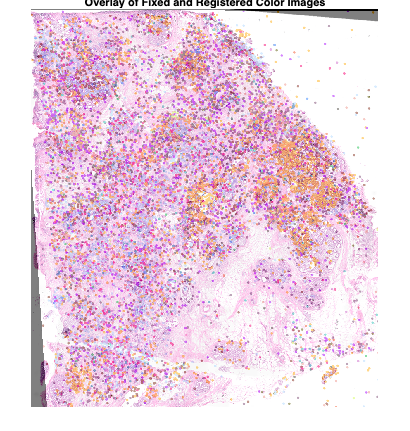


%% color image

% Define output view to match the fixed image dimensions
outputView = imref2d(size(fixedImage));

% Apply the transformation
registeredImage = imwarp(movingImage, tform, 'OutputView', outputView);
% Display overlay of fixed and registered images figure;

imshowpair(fixedImage, registeredImage, 'blend');
title('Overlay of Fixed and Registered Color Images');


blendedImage = imfuse(fixedImage, registeredImage, 'blend')

blendedImage = 1363×1187×3 uint8 array
blendedImage(:,:,1) =

    98   109   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105   105  

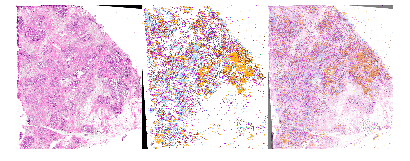

montage({fixedImage,registeredImage,blendedImage},'Size',[1 3])